## Modern Robotics

August 4th, 2024

Autor: Luis Andrés Alemán Sánchez

# Course 3 (Robot Dynamics) Project

Your job is to write code that simulates the motion of the UR5 for a specified amount of time (in seconds), from a specified initial configuration (at zero velocity), when zero torques are applied to the joints.  In other words, the robot simply falls in gravity. Gravity is *g*=9.81m/s2 in the −z direction, i.e., gravity acts downward.   The motion should be simulated with at least 100 integration steps per second.  Your program should calculate and record the robot joint angles at each step. This data should be saved as a .csv file, where each row has six numbers separated by commas. This .csv file is suitable for animation with the CoppeliaSim UR5 csv animation scene.

You will perform two simulations and make videos of each:

- The robot falling from the zero (home) configuration for 3 seconds.

- The robot falling from a configuration where all joints are at their zero position, except for joint 2, which is at −1 radian.  This simulation should last 5 seconds.

### Home Position

 [0, -90, 0, 0, +90, -90] (Deg)

[0, -1.5708, 0, 0, +1.5708, -1.5708] (Rad)

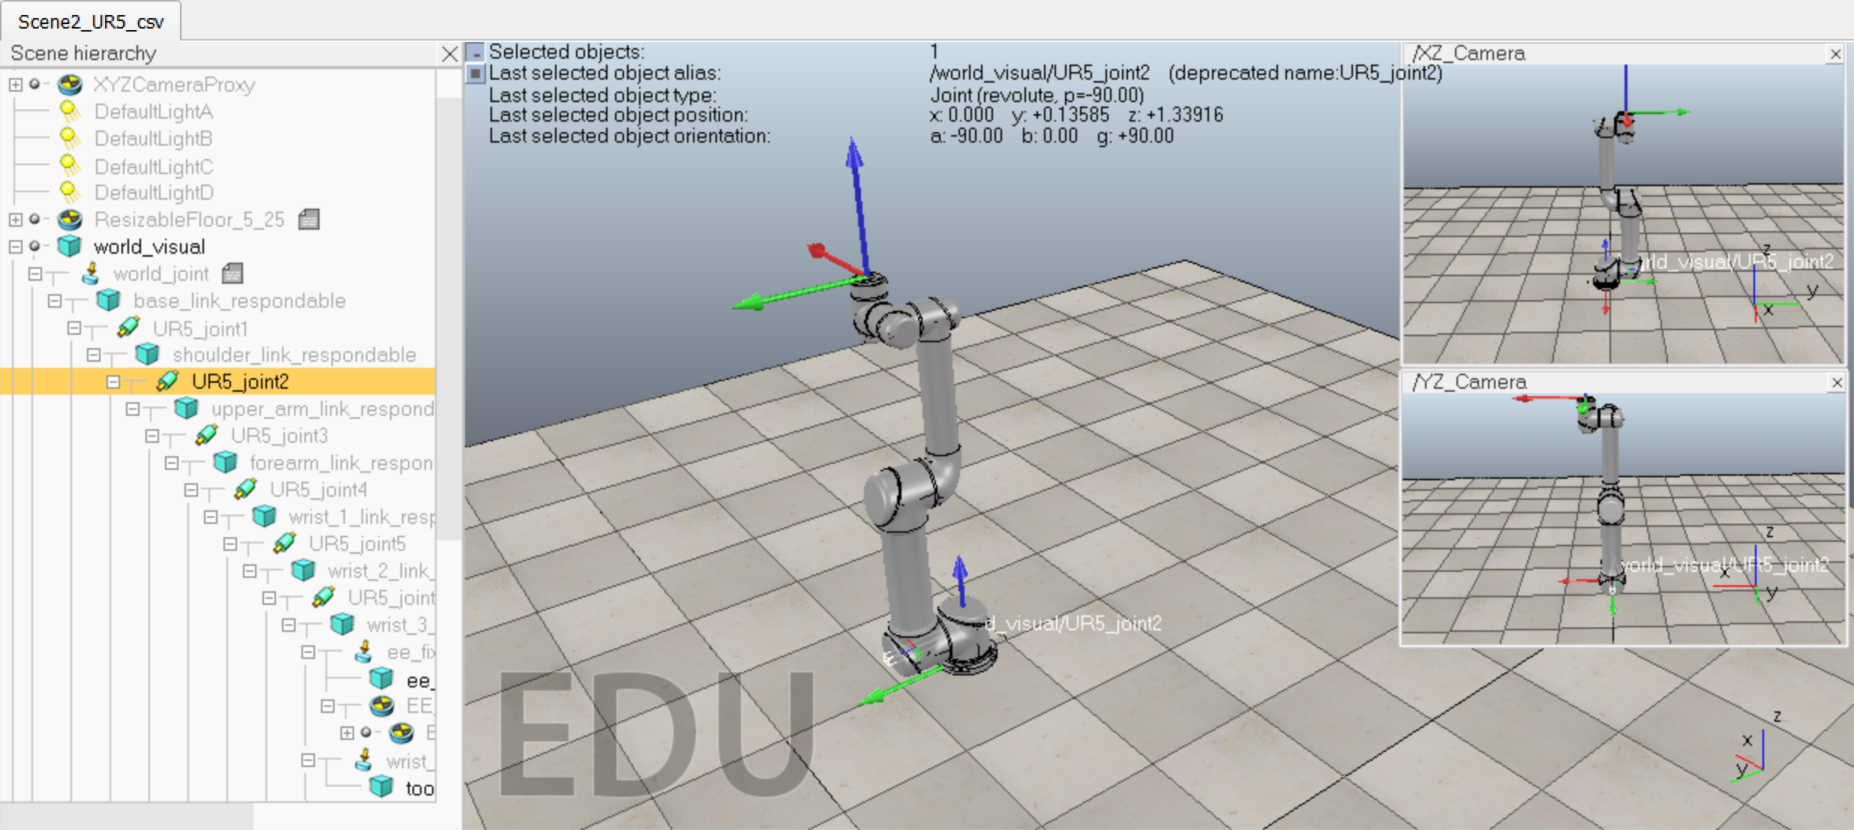

addpath('C:\Users\Lenovo\Documents\MATLAB\Modern Robotics\mr')

theta1 = simulation1;
csvwrite('simulation1.csv',theta1)

theta2 = simulation2;
csvwrite('simulation2.csv',theta2)

function theta = simulation1()

    M01 = [1, 0, 0, 0; 0, 1, 0, 0; 0, 0, 1, 0.089159; 0, 0, 0, 1];
    M12 = [0, 0, 1, 0.28; 0, 1, 0, 0.13585; -1, 0, 0, 0; 0, 0, 0, 1];
    M23 = [1, 0, 0, 0; 0, 1, 0, -0.1197; 0, 0, 1, 0.395; 0, 0, 0, 1];
    M34 = [0, 0, 1, 0; 0, 1, 0, 0; -1, 0, 0, 0.14225; 0, 0, 0, 1];
    M45 = [1, 0, 0, 0; 0, 1, 0, 0.093; 0, 0, 1, 0; 0, 0, 0, 1];
    M56 = [1, 0, 0, 0; 0, 1, 0, 0; 0, 0, 1, 0.09465; 0, 0, 0, 1];
    M67 = [1, 0, 0, 0; 0, 0, 1, 0.0823; 0, -1, 0, 0; 0, 0, 0, 1];
    G1 = diag([0.010267495893, 0.010267495893,  0.00666, 3.7, 3.7, 3.7]);
    G2 = diag([0.22689067591, 0.22689067591, 0.0151074, 8.393, 8.393, 8.393]);
    G3 = diag([0.049443313556, 0.049443313556, 0.004095, 2.275, 2.275, 2.275]);
    G4 = diag([0.111172755531, 0.111172755531, 0.21942, 1.219, 1.219, 1.219]);
    G5 = diag([0.111172755531, 0.111172755531, 0.21942, 1.219, 1.219, 1.219]);
    G6 = diag([0.0171364731454, 0.0171364731454, 0.033822, 0.1879, 0.1879, 0.1879]);
    Glist = cat(3, G1, G2, G3, G4, G5, G6);
    Mlist = cat(3, M01, M12, M23, M34, M45, M56, M67); 
    Slist = [0,         0,         0,         0,        0,        0;
             0,         1,         1,         1,        0,        1;
             1,         0,         0,         0,       -1,        0;
             0, -0.089159, -0.089159, -0.089159, -0.10915, 0.005491;
             0,         0,         0,         0,  0.81725,        0;
             0,         0,     0.425,   0.81725,        0,  0.81725];
    
    thetalist =[0, -1.5708, 0, 0, +1.5708, -1.5708]';
    dthetalist = [0,0,0,0,0,0]';
    Ftip = [0,0,0,0,0,0]';

    g = [0,0,-9.81];
    taulist = [0,0,0,0,0,0]';
    theta =[];
        
    N = 1000;    % Number of simulation steps
    tf = 3;      % Total simulation time (in seconds)
    dt = tf / N; % Time step (in seconds) | 3 / 1000 = 0.003 seconds

    for k = 0:N-1
        ddthetalist = ForwardDynamics(thetalist,dthetalist,taulist,g,Ftip,Mlist,Glist,Slist);
        thetalist = thetalist+dt*dthetalist;
        dthetalist = dthetalist+dt*ddthetalist;
        theta = [theta;thetalist'];
    end
end

function theta = simulation2()

    M01 = [1, 0, 0, 0; 0, 1, 0, 0; 0, 0, 1, 0.089159; 0, 0, 0, 1];
    M12 = [0, 0, 1, 0.28; 0, 1, 0, 0.13585; -1, 0, 0, 0; 0, 0, 0, 1];
    M23 = [1, 0, 0, 0; 0, 1, 0, -0.1197; 0, 0, 1, 0.395; 0, 0, 0, 1];
    M34 = [0, 0, 1, 0; 0, 1, 0, 0; -1, 0, 0, 0.14225; 0, 0, 0, 1];
    M45 = [1, 0, 0, 0; 0, 1, 0, 0.093; 0, 0, 1, 0; 0, 0, 0, 1];
    M56 = [1, 0, 0, 0; 0, 1, 0, 0; 0, 0, 1, 0.09465; 0, 0, 0, 1];
    M67 = [1, 0, 0, 0; 0, 0, 1, 0.0823; 0, -1, 0, 0; 0, 0, 0, 1];
    G1 = diag([0.010267495893, 0.010267495893,  0.00666, 3.7, 3.7, 3.7]);
    G2 = diag([0.22689067591, 0.22689067591, 0.0151074, 8.393, 8.393, 8.393]);
    G3 = diag([0.049443313556, 0.049443313556, 0.004095, 2.275, 2.275, 2.275]);
    G4 = diag([0.111172755531, 0.111172755531, 0.21942, 1.219, 1.219, 1.219]);
    G5 = diag([0.111172755531, 0.111172755531, 0.21942, 1.219, 1.219, 1.219]);
    G6 = diag([0.0171364731454, 0.0171364731454, 0.033822, 0.1879, 0.1879, 0.1879]);
    Glist = cat(3, G1, G2, G3, G4, G5, G6);
    Mlist = cat(3, M01, M12, M23, M34, M45, M56, M67); 
    Slist = [0,         0,         0,         0,        0,        0;
             0,         1,         1,         1,        0,        1;
             1,         0,         0,         0,       -1,        0;
             0, -0.089159, -0.089159, -0.089159, -0.10915, 0.005491;
             0,         0,         0,         0,  0.81725,        0;
             0,         0,     0.425,   0.81725,        0,  0.81725];
    
    thetalist =[0,-1,0,0,0,0]';
    dthetalist = [0,0,0,0,0,0]';
    Ftip = [0,0,0,0,0,0]';

    g = [0,0,-9.81];
    taulist = [0,0,0,0,0,0]';
    theta =[];
        
    N = 1000;    % Number of simulation steps
    tf = 5;      % Total simulation time (in seconds)
    dt = tf / N; % Time step (in seconds) | 5 / 1000 = 0.005 seconds

    for k = 0:N-1
        ddthetalist = ForwardDynamics(thetalist,dthetalist,taulist,g,Ftip,Mlist,Glist,Slist);
        thetalist = thetalist+dt*dthetalist;
        dthetalist = dthetalist+dt*ddthetalist;
        theta = [theta;thetalist'];
    end
end